## Perovskite solar cell modeling

Yeraldin Velez Galvis

yeraldinvelez236975@correo.itm.edu.co

#### *Abstract:*

The analysis of the energy efficiency of perovskite solar cells is of great importance to evaluate their performance and obtain higher efficiency values. The purpose of the current research is to create a simulation methodology for perovskite solar cells, optimizing the geometrical and photoelectric parameters, which will be stored for further processing. The resulting database will be used to train a machine learning algorithm to predict the performance of the cells based on their energy efficiency, having as inputs the design parameters, both electrical and geometrical [1]

Multiple investigations have found that the energy efficiency of solar cells is directly affected by the thickness of their layers. Analysis and optimization of this parameter can lead to better performing devices. Therefore, in the present work, the variation of the thicknesses of the films that compose the cell in 1D will be performed and the efficiency values are extracted, which will be plotted to analyze their behavior when varying the thicknesses of the electron transport layer (ETL), the perovskite layer (PVK) and the hole transport layer (HTL). In addition, the complexity of the algorithms is analyzed and alternatives are proposed to optimize the time and improve their performance [2]. 

The code presented below is developed by connecting COMSOL (simulation software for solar cells) and Matlab, where the classes and methods are specific to LiveLink, which allows Matlab to be connected to the COMSOl server. Therefore, numerical analysis of the cell can be performed and the results of the electrical variables of the model can be visualized. Thus, the variable called "model" allows the simulation to be loaded into Matlab and acts as an object to apply classes and methods later in the algorithm.

## Variation of ETL thickness algorithm

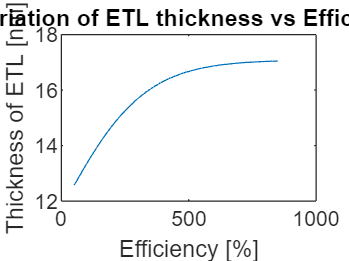

clear all
clc

model = mphload("Ejemplo1DaS.mph"); %Load the model

% Define thickness values and get the length of the array
thickness_ETL = 50:10:1000;
num_ETL = numel(thickness_ETL);

% Create zeros array for the efficency
efficiency_ETL = zeros(1, num_ETL);
x_ETL = zeros(1, num_ETL);

for i = 1:num_ETL
    t_ETL = thickness_ETL(i);
    x_ETL(i) = t_ETL;
    model.param.set('thickness_ETL', t_ETL);%It changes the parameter value in COMSOL
    mphrun(model,'study');%Run the study
    new_data = model.result.numerical('gev1').getReal;%Get the calculated value of efficiency from the simulation
    efficiency_ETL(i) = new_data;%Save all the generated values of efficency
end

plot(thickness_ETL, efficiency_ETL)
ylabel("Efficiency [%]")
xlabel("Thickness of ETL [nm]")
title("Variation of ETL thickness vs Efficency")

The above algorithm can be used to vary the other 2 design parameters. Therefore, the thicknesses of the 3 different layers are modified and a graph is generated for each one having as x-axis the generated efficiency and as y-axis the range of thicknesses:

## Variation of perovskite thickness algorithm

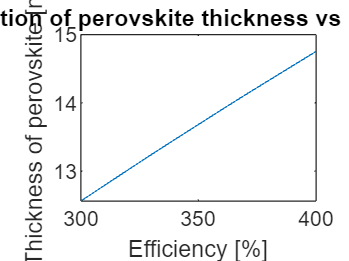

clear all

clc

model = mphload("Ejemplo1DaS.mph");%Load the model

% Define thickness values and get the length of the array
thickness_PVK = 50:10:1000;
num_PVK = numel(thickness_PVK);

% Create zeros array for the efficency
efficiency_PVK = zeros(1, num_PVK);
x_PVK = zeros(1, num_PVK);

for i = 1:num_PVK
    t_PVK = thickness_PVK(i);
    x_PVK(i) = t_PVK;
    model.param.set('thickness_PVK', t_PVK);%It changes the parameter value in COMSOL
    mphrun(model,'study');%Run the study
    new_data2 = model.result.numerical('gev1').getReal;%Get the calculated value of efficiency from the simulation
    efficiency_PVK(i) = new_data2;%Save all the generated values of efficency
end

plot(thickness_PVK, efficiency_PVK)
ylabel("Efficiency [%]")
xlabel("Thickness of perovskite [nm]")
title("Variation of perovskite thickness vs Efficency")


To modify the values of the thicknesses, a for cycle is used which goes through a number of steps given by the range of thicknesses to be evaluated. Although it is not possible to access the libraries and classes that govern the model, it is known that the COMSOL software performs a cycle to apply an input voltage in the cell and to perform the calculation of the physical phenomena present in the cell, another cycle is executed for the evaluation of results by means of the finite element method. With this in mind, it is understood that when executing the command "mphrun" two cycles are used, plus the cycle that is being used to traverse the vector and vary the thickness in each layer gives as a result a complexity type O(n). As the software is closed source it cannot be ruled out that it contains more cycles. Therefore, it can be said that the algorithms shown below can present an O(n) complexity.

## Variation of HTL thickness algorithm

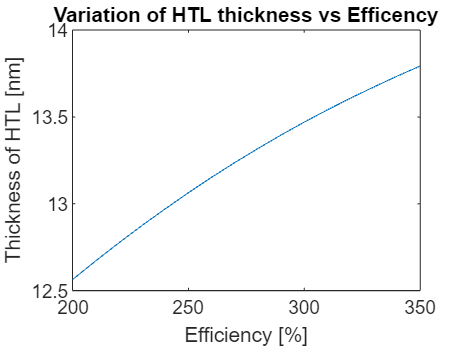


clear all
clc

model = mphload("Ejemplo1DaS.mph");%Load the model

% Define thickness values and get the length of the array
thickness_HTL = 50:10:1000;
num_HTL = numel(thickness_HTL);

% Create zeros array for the efficency
efficiency_HTL = zeros(1, num_HTL);
x_HTL = zeros(1, num_HTL);

for i = 1:num_HTL
    t_HTL = thickness_HTL(i);
    x_HTL(i) = t_HTL;
    model.param.set('thickness_HTL', t_HTL);%It changes the parameter value in COMSOL
    mphrun(model,'study');%Run the study
    new_data3 = model.result.numerical('gev1').getReal;%Get the calculated value of efficiency from the simulation
    efficiency_HTL(i) = new_data3;%Save all the generated values of efficency
end

plot(thickness_HTL, efficiency_HTL)
ylabel("Efficiency [%]")
xlabel("Thickness of HTL [nm]")
title("Variation of HTL thickness vs Efficency")

An attempt was made to reduce the complexity for the algorithms. However, it is necessary to traverse the thickness vector to evaluate the efficiency at each point. An alternative proposed below suggests the use of while cycles to traverse the vector. In the end, the previous challenge remains. Therefore, this is discarded as a possible solution and it is concluded that in this case it is not possible to use a resource other than cycles, since the classes, functions and methods that can be implemented in this application are kept under strict confidentiality and it is not possible to apply methodologies different from those established in LiveLink (name of the Matlab-COMSOL connection). 

It is important to mention that a limited number of thicknesses are used. Because of the complexity of the simulations and the computational resources required, the workstation will run out of memory.

model = mphload("Ejemplo1DaS.mph");

% Define thickness values
thickness_values = 300:10:400;
num_values = numel(thickness_values);

% Preallocate arrays
efficiency_PVK = zeros(1, num_values);
x_PVK = zeros(1, num_values);

% Loop counter initialization (outside the loop)
i = 1;

% While loop for iterating through thickness values
while i <= num_values
  t_PVK = thickness_values(i);
  x_PVK(i) = t_PVK;
  model.param.set('thickness_PVK', t_PVK);
  mphrun(model,'study');
  new_data2 = model.result.numerical('gev1').getReal;
  efficiency_PVK(i) = new_data2;
  
  % Increment counter inside the loop
  i = i + 1;
end

plot(thickness_values, efficiency_PVK)
xlabel("Eficiencia energetica [%]")
ylabel("Espesor de la capa de perovskita [nm]")
title("Variación de la eficiencia en función del espesor de ETL")



## **Discussion of results**

An increasing behavior for the efficiency can be observed as the energy efficiency increases. This can be seen in all the graphs generated, being of vital importance. It is understood that the larger the area where solar radiation is incident, the higher the resulting energy efficiency should be [3]. With this in mind, the plan for future work is to perform nested for cycles to find the combination of thicknesses that generate the highest energy efficiency. 

## References

[1] Minbashi, M., & Yazdani, E. (2022). Comprehensive study of anomalous hysteresis behavior in perovskite-based solar cells. *Scientific Reports*, *12*(1). https://doi.org/10.1038/s41598-022-19194-5

[2] Ouslimane, T., Et-taya, L., Elmaimouni, L., & Benami, A. (2021). Impact of absorber layer thickness, defect density, and operating temperature on the performance of MAPbI3 solar cells based on ZnO electron transporting material. *Heliyon*, *7*(3), e06379. https://doi.org/10.1016/j.heliyon.2021.e06379

[3] Vélez, J., Sepúlveda, F., Botero, M., Otalora, C., & Camacho, C. (2023). Absorber layer thickness as a new feature in statistical learning tools of Perovskite solar cells. *Journal of Applied Research and Technology*, *21*, 858–865. https://doi.org/10.22201/ICAT.24486736E.2023.21.5.2057